trainData = readmatrix('mnist_train.csv')

trainData =      5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0 

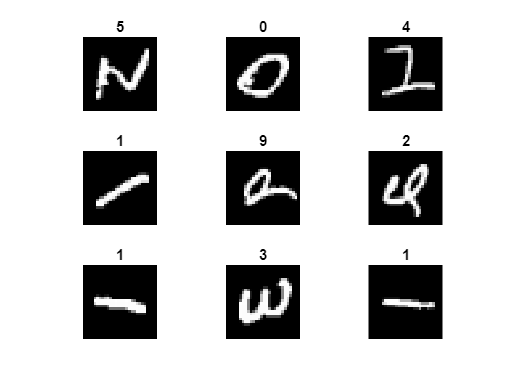

testData = readmatrix('mnist_test.csv');
% Training data
trainLabels = trainData(:, 1);               % Extract labels
trainImages = trainData(:, 2:end);           % Extract pixel values

% Testing data
testLabels = testData(:, 1);
testImages = testData(:, 2:end);

% Reshape training images
numTrainSamples = size(trainImages, 1);
trainImages = reshape(trainImages', [28, 28, 1, numTrainSamples]);

% Reshape testing images
numTestSamples = size(testImages, 1);
testImages = reshape(testImages', [28, 28, 1, numTestSamples]);

trainImages = double(trainImages) / 255;
testImages = double(testImages) / 255;

trainLabels = categorical(trainLabels);
testLabels = categorical(testLabels);
figure;
for i = 1:9
    subplot(3, 3, i);
    imshow(trainImages(:, :, 1, i));
    title(string(trainLabels(i)));
end


size(trainImages)  % Should return [28, 28, 1, numTrainSamples]

ans =           28          28           1       60000


size(testImages)   % Should return [28, 28, 1, numTestSamples]

ans =           28          28           1       10000


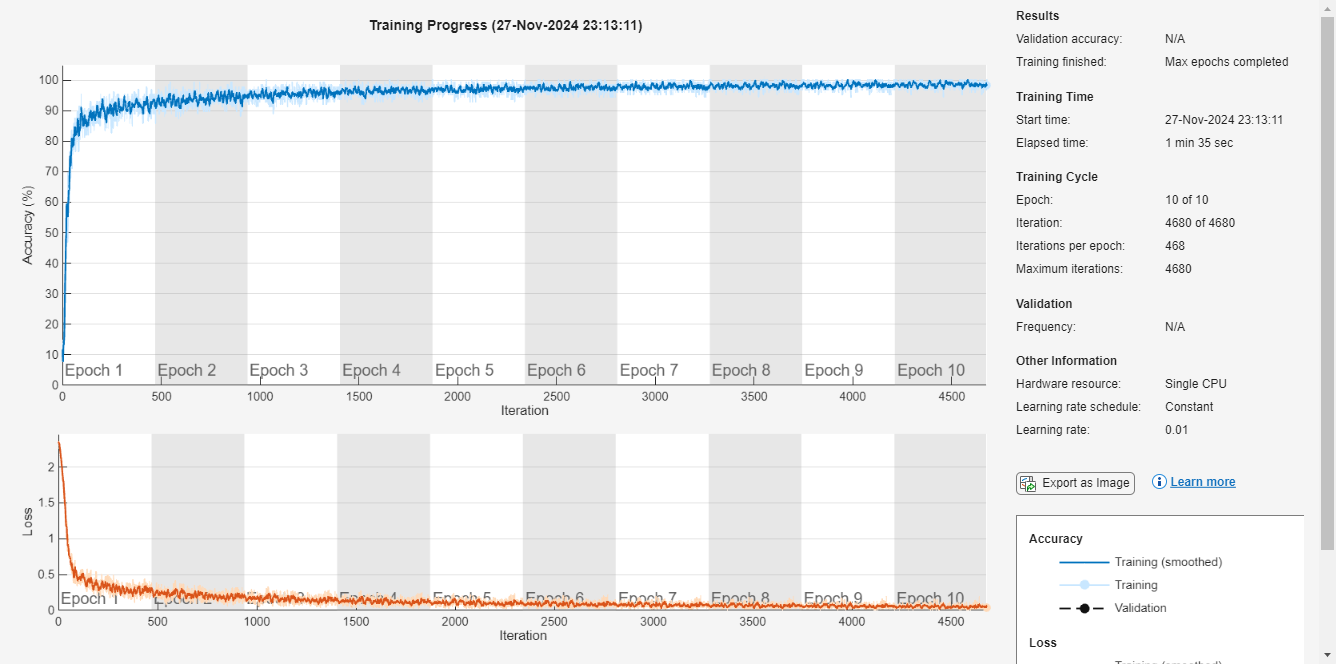


layers = [
    imageInputLayer([28, 28, 1], 'Name', 'input')

    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu1')

    fullyConnectedLayer(64, 'Name', 'fc2')
    reluLayer('Name', 'relu2')

    fullyConnectedLayer(10, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    
    classificationLayer('Name', 'output')
];
options = trainingOptions('sgdm', ... % Use stochastic gradient descent with momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Plots', 'training-progress', ...
    'Verbose', false);
net = trainNetwork(trainImages, trainLabels, layers, options);

% Predict labels for test images
predictedLabels = classify(net, testImages);

% Calculate accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 97.48%


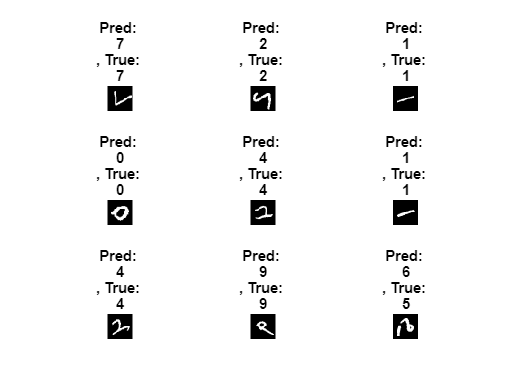

figure;
for i = 1:9
    subplot(3, 3, i);
    imshow(testImages(:, :, 1, i));
    title(['Pred: ', string(predictedLabels(i)), ...
           ', True: ', string(testLabels(i))]);
end

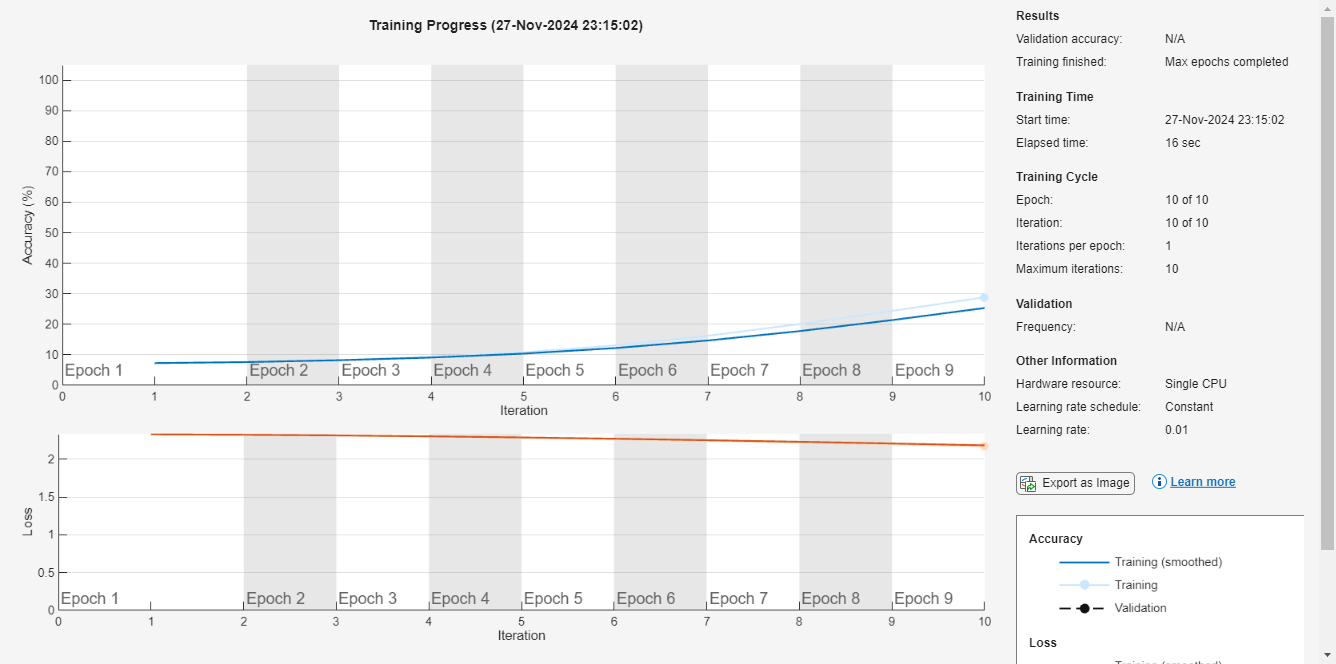

%batch
options_batch = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', numTrainSamples, ... % Use all training samples
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train the network
net_batch = trainNetwork(trainImages, trainLabels, layers, options_batch);


% Evaluate performance
predictedLabels_batch = classify(net_batch, testImages);
accuracy_batch = sum(predictedLabels_batch == testLabels) / numel(testLabels);
disp(['Batch Gradient Descent Accuracy: ', num2str(accuracy_batch * 100), '%']);

Batch Gradient Descent Accuracy: 33.51%


%SGD.................................................................................................................................
options_sgd = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 1, ... % Single sample at a time
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train the network
net_sgd = trainNetwork(trainImages, trainLabels, layers, options_sgd);

% Evaluate performance
predictedLabels_sgd = classify(net_sgd, testImages);
accuracy_sgd = sum(predictedLabels_sgd == testLabels) / numel(testLabels);
disp(['Stochastic Gradient Descent Accuracy: ', num2str(accuracy_sgd * 100), '%']);

Stochastic Gradient Descent Accuracy: 26.31%


%minibatch.....................................................................................................................................
options_minibatch = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ... % Small batch of samples
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train the network
net_minibatch = trainNetwork(trainImages, trainLabels, layers, options_minibatch);

% Evaluate performance
predictedLabels_minibatch = classify(net_minibatch, testImages);
accuracy_minibatch = sum(predictedLabels_minibatch == testLabels) / numel(testLabels);
disp(['Mini-batch Gradient Descent Accuracy: ', num2str(accuracy_minibatch * 100), '%']);

Mini-batch Gradient Descent Accuracy: 87.94%


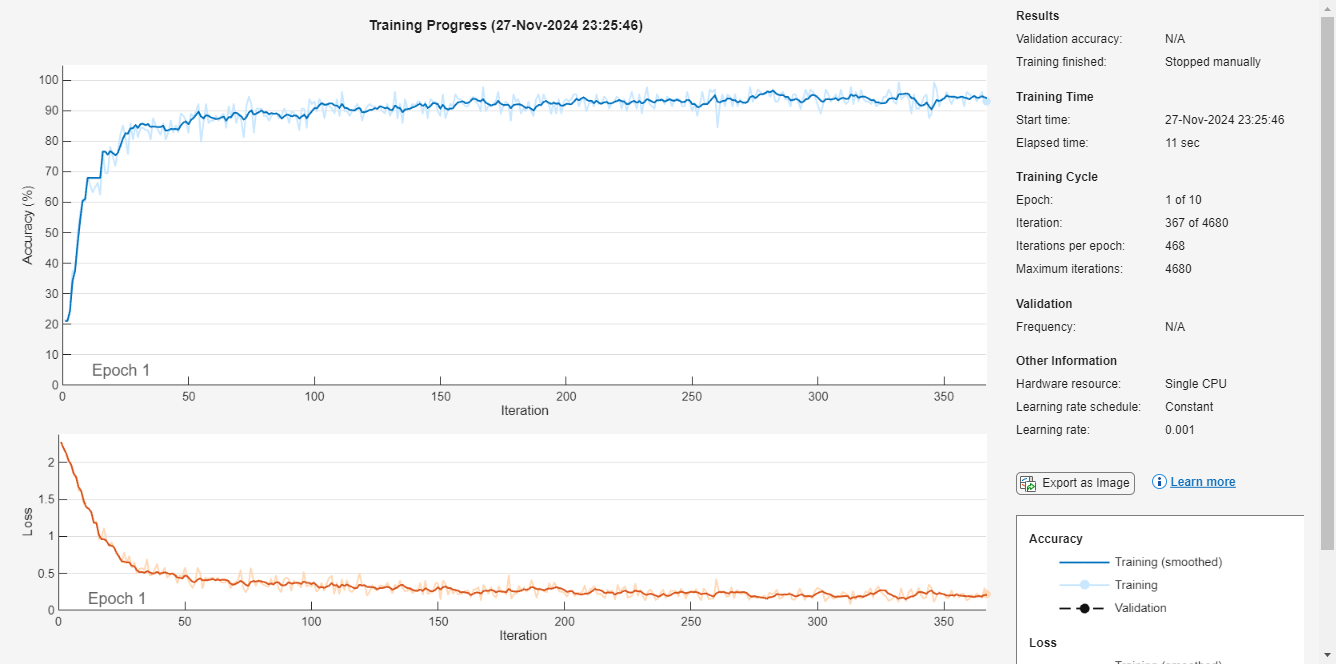

%Adam Optimizer
options_adam = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train the network
net_adam = trainNetwork(trainImages, trainLabels, layers, options_adam);


% Evaluate performance
predictedLabels_adam = classify(net_adam, testImages);
accuracy_adam = sum(predictedLabels_adam == testLabels) / numel(testLabels);
disp(['Adam Optimizer Accuracy: ', num2str(accuracy_adam * 100), '%']);

Adam Optimizer Accuracy: 94.58%
